clear; clc;
D   = 12;
lb  = -ones(1,D);          % 归一化空间 [-1,1]
ub  =  ones(1,D);
pop = 200;
maxIt=500;
lb_phy = [70 0 70 0 70 0 0 0 0 0 0 0];
ub_phy = [140 2*pi 140 2*pi 140 2*pi 10 15 10 15 10 15];
% 目标函数句柄：粒子群永远只看到 [-1,1]
fitFcn = @cal_shelf_norm;

% 运行 AM_PSO
[x_norm_best, f_best, trace] = AM_PSO(fitFcn, D, pop, maxIt, lb, ub);

% 如果想看真实物理量
x_phy_best = (x_norm_best + 1)/2 .* (ub_phy - lb_phy) + lb_phy;
fprintf('最优物理量：'); disp(x_phy_best);

最优物理量：  列 1 至 11

  125.7976    0.0892  136.0109    3.7047   78.7615    2.4768    0.9826    0.0040    9.4010    9.0956    8.7527

  列 12

   14.6774



fprintf('最大遮蔽时长：%.3f s\n', -f_best);  % 原函数返回负值

最大遮蔽时长：8.810 s


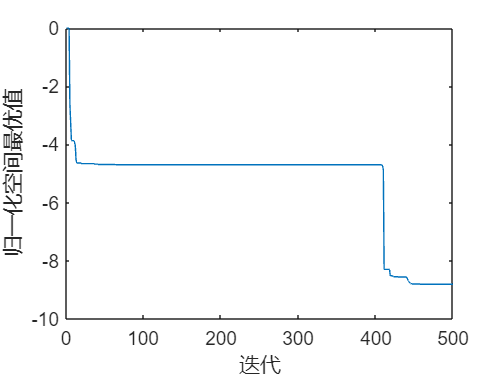

plot(trace); xlabel('迭代'); ylabel('归一化空间最优值');